# Location Analysis

clear;
clc;

## Wild Type

### n=1

WT_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=1/results_from_time_0/location.dat";
[WT_1_LuminalLocation, WT_1_MyoepithelialLocation, WT_1_r, WT_1_r2] = CellPosition(WT_1);

### n=2

WT_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=2/results_from_time_0/location.dat";
[WT_2_LuminalLocation, WT_2_MyoepithelialLocation, WT_2_r, WT_2_r2] = CellPosition(WT_2);

### n=3

WT_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=3/results_from_time_0/location.dat";
[WT_3_LuminalLocation, WT_3_MyoepithelialLocation, WT_3_r, WT_3_r2] = CellPosition(WT_3);

### n=4

WT_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=4/results_from_time_0/location.dat";
[WT_4_LuminalLocation, WT_4_MyoepithelialLocation, WT_4_r, WT_4_r2] = CellPosition(WT_4);

### n=5

WT_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=5/results_from_time_0/location.dat";
[WT_5_LuminalLocation, WT_5_MyoepithelialLocation, WT_5_r, WT_5_r2] = CellPosition(WT_5);

% Box plot final position of cells

figure 

WTluminal = WT_1_r(end,:);
WTmyo = WT_1_r2(end,:);
g = [WTluminal WTmyo];
C = [zeros(1,length(WTluminal)) ones(1,length(WTmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

Error using swarmchart (line 57)
X and Y must be vectors of the same length.


ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_WT.tiff');
movefile('CellPosition_WT.tiff', folder);

Error using matlab.internal.builtinhelper.repmat (line 53)
Replication factors must be a row vector of integers or integer scalars.

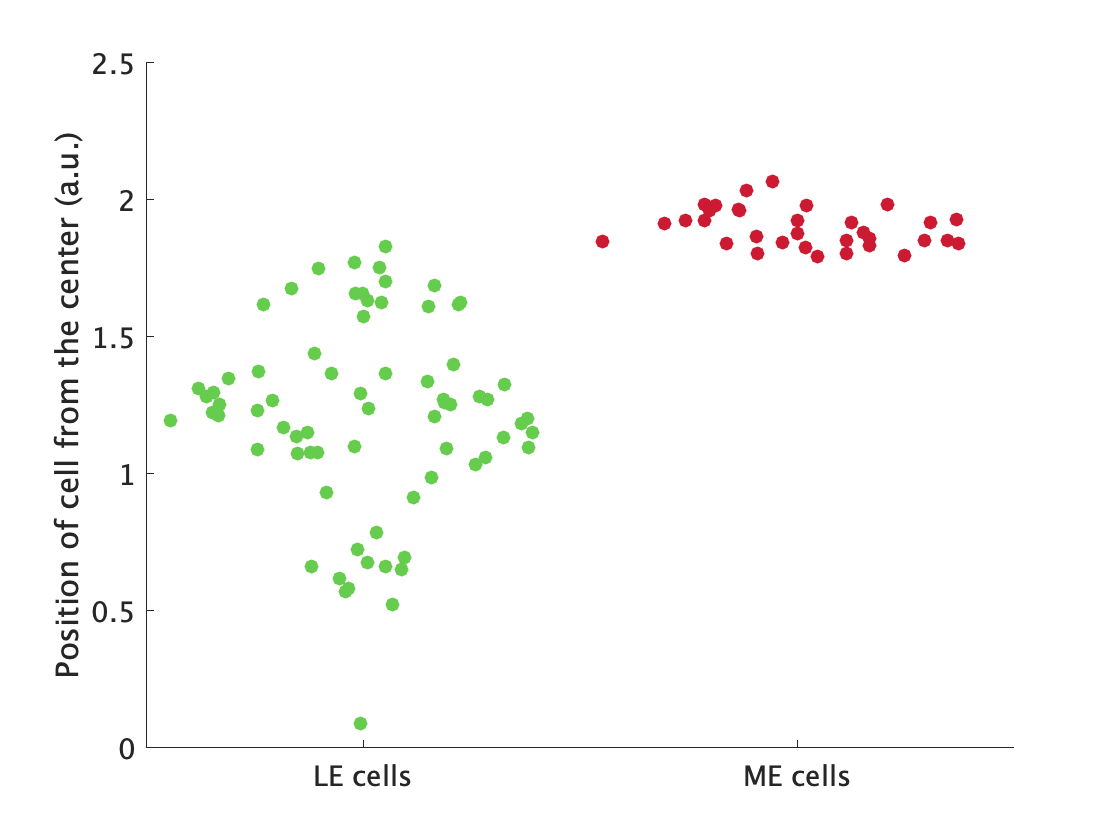

clf

WTluminal = WT_1_r(end,:);
LE1 = WTluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

WTmyo = WT_1_r2(end,:);
ME1 = WTmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_WT.tiff');

movefile('CellPosition_WT.tiff', folder);

% combine data from all experiments
WTLEposition = cat(1,WT_1_r(end,:),WT_2_r(end,:),WT_3_r(end,:),WT_4_r(end,:),WT_5_r(end,:));
WTMEposition = cat(1,WT_1_r2(end,:),WT_2_r2(end,:),WT_3_r2(end,:),WT_4_r2(end,:),WT_5_r2(end,:));

%Calculate Mean
WTLEaverage = mean(WTLEposition,2);
WTMEaverage = mean(WTMEposition,2);

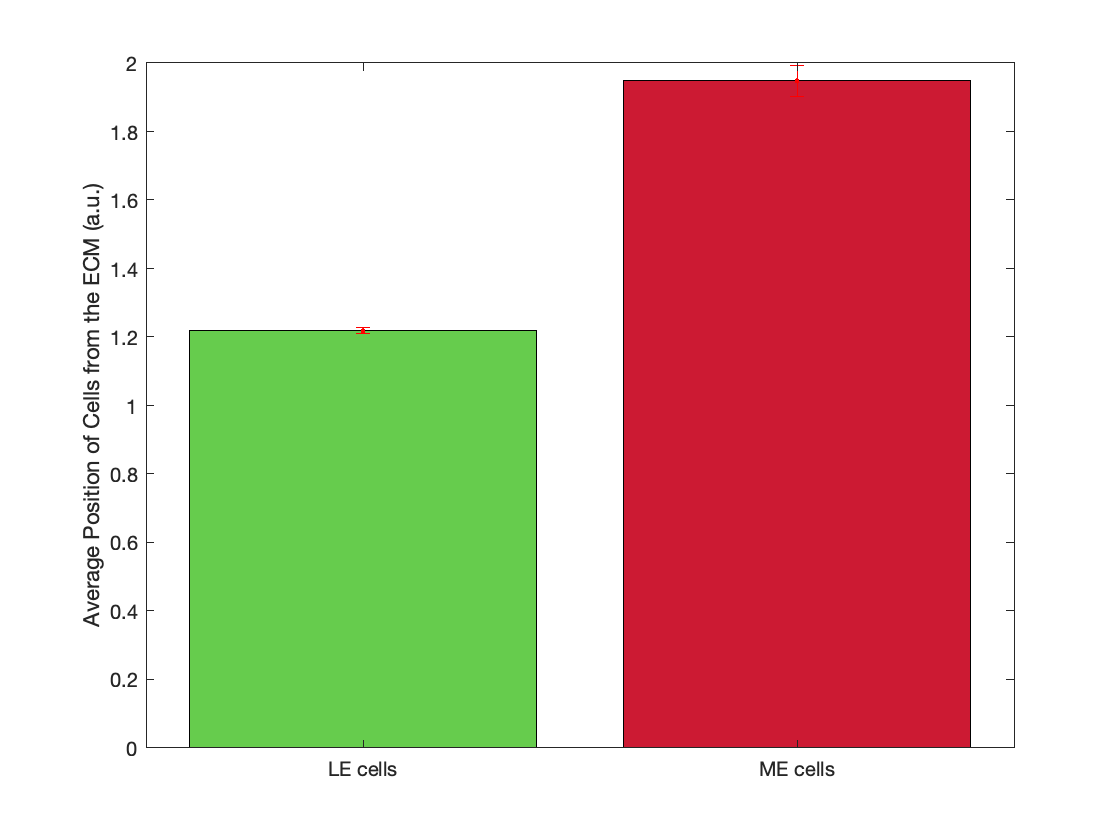

% plot average position of cells include data from all n=5 

%Calculate Mean and Standard Deviation
WTmeanLE = mean(WTLEaverage);
WTmeanME = mean(WTMEaverage);

y = cat(2, WTmeanLE, WTmeanME);

WTstdLE = std(WTLEaverage);
WTstdME = std(WTMEaverage);

error = cat(2, WTstdLE, WTstdME);

x=categorical({'LE cells', 'ME cells'});

b = bar(x,y);

%Make SD error bars 
hold on
errorbar(x,y, error, '.r')
hold off

ylabel('Average Position of Cells from the ECM (a.u.)') 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

hold off

folder = '~/Desktop/';
exportgraphics(gca, 'AverageCellPosition_WT.pdf');

movefile('AverageCellPosition_WT.pdf', folder);

## ME B1 KO

### n=1

MEB1KO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=1/results_from_time_0/location.dat";
[MEB1KO_1_LuminalLocation, MEB1KO_1_MyoepithelialLocation, MEB1KO_1_r, MEB1KO_1_r2] = CellPosition(MEB1KO_1);

### n=2

MEB1KO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=2/results_from_time_0/location.dat";
[MEB1KO_2_LuminalLocation, MEB1KO_2_MyoepithelialLocation, MEB1KO_2_r, MEB1KO_2_r2] = CellPosition(MEB1KO_2);

### n=3

MEB1KO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=3/results_from_time_0/location.dat";
[MEB1KO_3_LuminalLocation, MEB1KO_3_MyoepithelialLocation, MEB1KO_3_r, MEB1KO_3_r2] = CellPosition(MEB1KO_3);

### n=4

MEB1KO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=4/results_from_time_0/location.dat";
[MEB1KO_4_LuminalLocation, MEB1KO_4_MyoepithelialLocation, MEB1KO_4_r, MEB1KO_4_r2] = CellPosition(MEB1KO_4);

### n=5

MEB1KO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEB1KO/n=5/results_from_time_0/location.dat";
[MEB1KO_5_LuminalLocation, MEB1KO_5_MyoepithelialLocation, MEB1KO_5_r, MEB1KO_5_r2] = CellPosition(MEB1KO_5);

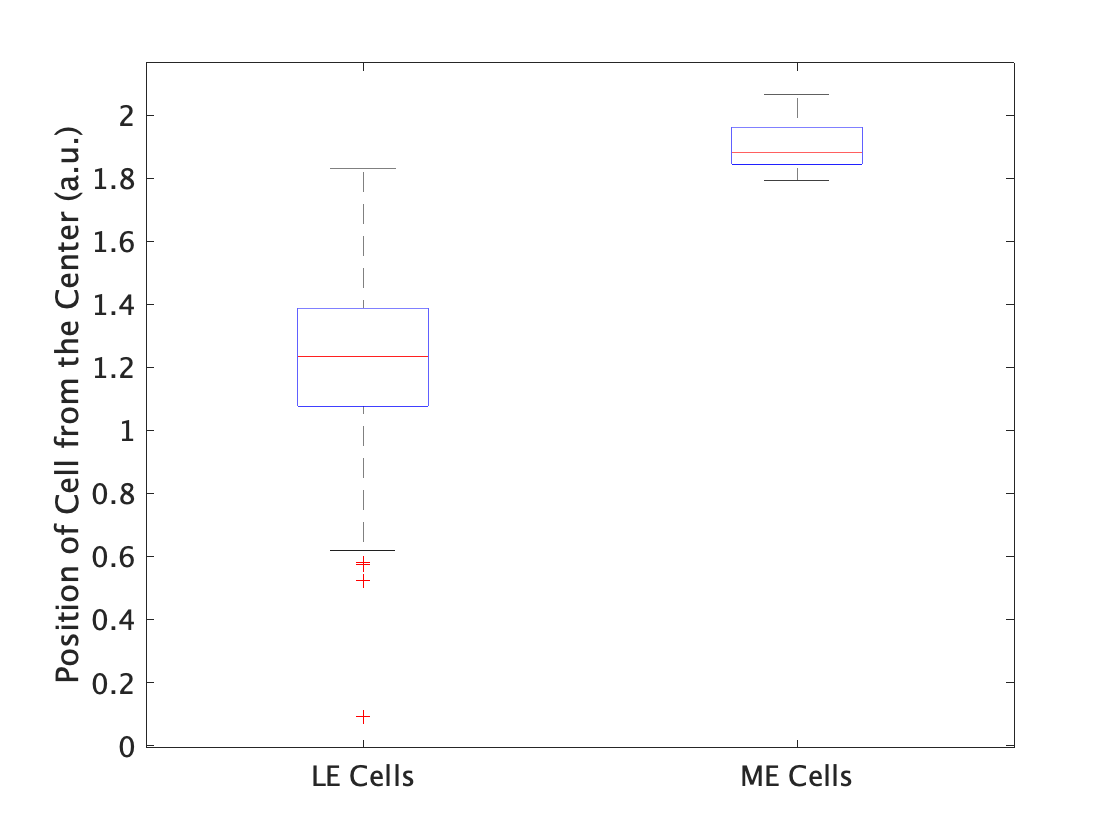

% Box plot final position of cells

figure 

MEB1KOluminal = MEB1KO_1_r(end,:);
MEB1KOmyo = MEB1KO_1_r2(end,:);
g = [MEB1KOluminal MEB1KOmyo];
C = [zeros(1,length(MEB1KOluminal)) ones(1,length(MEB1KOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_MEB1KO.tiff');

movefile('CellPosition_MEB1KO.tiff', folder);

clf

MEB1KOluminal = MEB1KO_1_r(end,:);
LE1 = MEB1KOluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

MEB1KOmyo = MEB1KO_1_r2(end,:);
ME1 = MEB1KOmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_MEB1KO.tiff');

movefile('CellPosition_MEB1KO.tiff', folder);

% combine data from all experiments
MEB1KOLEposition = cat(1,MEB1KO_1_r(end,:),MEB1KO_2_r(end,:),MEB1KO_3_r(end,:),MEB1KO_4_r(end,:),MEB1KO_5_r(end,:));
MEB1KOMEposition = cat(1,MEB1KO_1_r2(end,:),MEB1KO_2_r2(end,:),MEB1KO_3_r2(end,:),MEB1KO_4_r2(end,:),MEB1KO_5_r2(end,:));

%Calculate Mean
MEB1KOLEaverage = mean(MEB1KOLEposition,2);
MEB1KOMEaverage = mean(MEB1KOMEposition,2);

% plot average position of cells include data from all n=5 

%Calculate Mean and Standard Deviation
MEB1KOmeanLE = mean(MEB1KOLEaverage);
MEB1KOmeanME = mean(MEB1KOMEaverage);

y = cat(2, MEB1KOmeanLE, MEB1KOmeanME);

MEB1KOstdLE = std(MEB1KOLEaverage);
MEB1KOstdME = std(MEB1KOMEaverage);

error = cat(2, MEB1KOstdLE, MEB1KOstdME);

x=categorical({'LE cells', 'ME cells'});

b = bar(x,y);

%Make SD error bars 
hold on
errorbar(x,y, error, '.r')
hold off

ylabel('Average Position of Cells from the ECM (a.u.)') 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

hold off

folder = '~/Desktop/';
exportgraphics(gca, 'AverageCellPosition_MEB1KO.pdf');
movefile('AverageCellPosition_MEB1KO.pdf', folder);

## ME KO

### n=1

MEKO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=1/results_from_time_0/location.dat";
[MEKO_1_LuminalLocation, MEKO_1_MyoepithelialLocation, MEKO_1_r, MEKO_1_r2] = CellPosition(MEKO_1);

### n=2

MEKO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=2/results_from_time_0/location.dat";
[MEKO_2_LuminalLocation, MEKO_2_MyoepithelialLocation, MEKO_2_r, MEKO_2_r2] = CellPosition(MEKO_2);

### n=3

MEKO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=3/results_from_time_0/location.dat";
[MEKO_3_LuminalLocation, MEKO_3_MyoepithelialLocation, MEKO_3_r, MEKO_3_r2] = CellPosition(MEKO_3);

### n=4

MEKO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=4/results_from_time_0/location.dat";
[MEKO_4_LuminalLocation, MEKO_4_MyoepithelialLocation, MEKO_4_r, MEKO_4_r2] = CellPosition(MEKO_4);

### n=5

MEKO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/MEKO/n=5/results_from_time_0/location.dat";
[MEKO_5_LuminalLocation, MEKO_5_MyoepithelialLocation, MEKO_5_r, MEKO_5_r2] = CellPosition(MEKO_5);

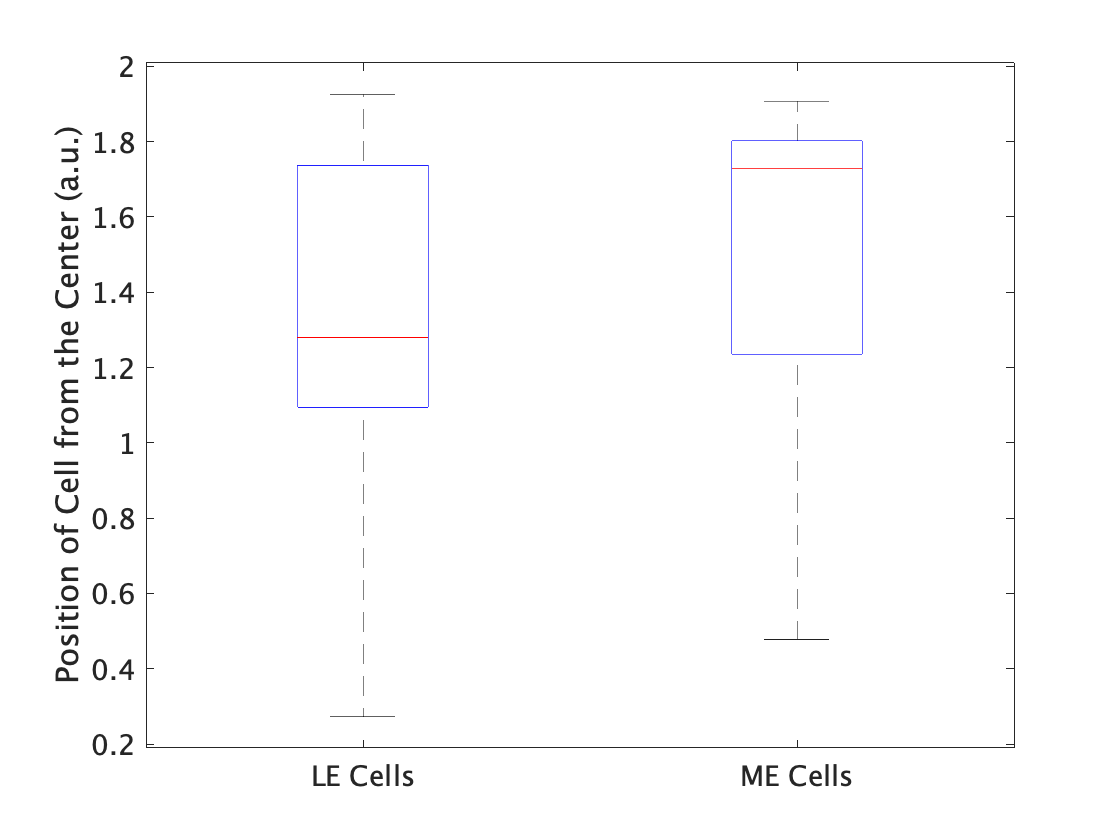

% Box plot final position of cells

figure 

MEKOluminal = MEKO_1_r(end,:);
MEKOmyo = MEKO_1_r2(end,:);
g = [MEKOluminal MEKOmyo];
C = [zeros(1,length(MEKOluminal)) ones(1,length(MEKOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_MEKO.tiff');

movefile('CellPosition_MEKO.tiff', folder);

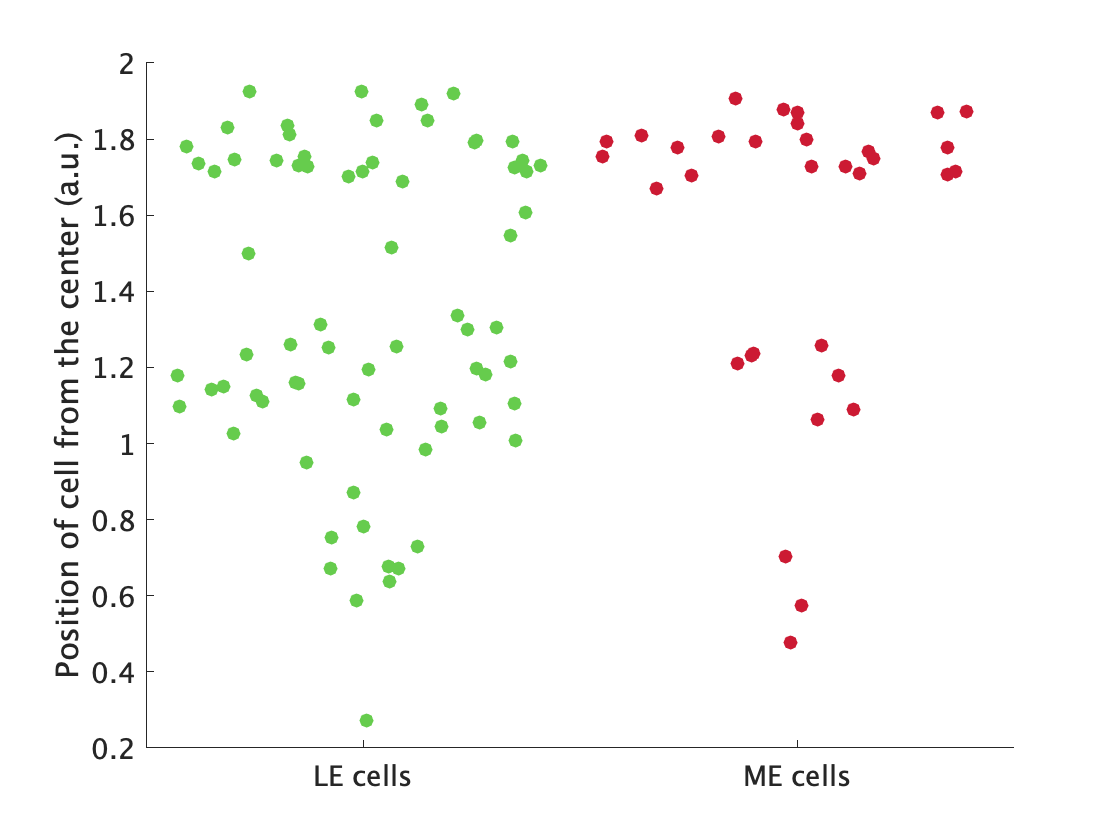

clf

MEKOluminal = MEKO_1_r(end,:);
LE1 = MEKOluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

MEKOmyo = MEKO_1_r2(end,:);
ME1 = MEKOmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_MEKO.tiff');

movefile('CellPosition_MEKO.tiff', folder);

% combine data from all experiments
MEKOLEposition = cat(1,MEKO_1_r(end,:),MEKO_2_r(end,:),MEKO_3_r(end,:),MEKO_4_r(end,:),MEKO_5_r(end,:));
MEKOMEposition = cat(1,MEKO_1_r2(end,:),MEKO_2_r2(end,:),MEKO_3_r2(end,:),MEKO_4_r2(end,:),MEKO_5_r2(end,:));

%Calculate Mean
MEKOLEaverage = mean(MEKOLEposition,2);
MEKOMEaverage = mean(MEKOMEposition,2);

% plot average position of cells include data from all n=5 

%Calculate Mean and Standard Deviation
MEKOmeanLE = mean(MEKOLEaverage);
MEKOmeanME = mean(MEKOMEaverage);

y = cat(2,MEKOmeanLE, MEKOmeanME);

MEKOstdLE = std(MEKOLEaverage);
MEKOstdME = std(MEKOMEaverage);

error = cat(2,MEKOstdLE, MEKOstdME);

x=categorical({'LE cells', 'ME cells'});

b = bar(x,y);

%Make SD error bars 
hold on
errorbar(x,y, error, '.r')
hold off

ylabel('Average Position of Cells from the ECM (a.u.)') 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

hold off

folder = '~/Desktop/';
exportgraphics(gca, 'AverageCellPosition_MEKO.pdf');
movefile('AverageCellPosition_MEKO.pdf', folder);

## LE B1 KO

### n=1

LEB1KO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEB1KO/n=1/results_from_time_0/location.dat";
[LEB1KO_1_LuminalLocation, LEB1KO_1_MyoepithelialLocation, LEB1KO_1_r, LEB1KO_1_r2] = CellPosition(LEB1KO_1);

### n=2

LEB1KO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEB1KO/n=2/results_from_time_0/location.dat";
[LEB1KO_2_LuminalLocation, LEB1KO_2_MyoepithelialLocation, LEB1KO_2_r, LEB1KO_2_r2] = CellPosition(LEB1KO_2);

### n=3

LEB1KO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEB1KO/n=3/results_from_time_0/location.dat";
[LEB1KO_3_LuminalLocation, LEB1KO_3_MyoepithelialLocation, LEB1KO_3_r, LEB1KO_3_r2] = CellPosition(LEB1KO_3);

### n=4

LEB1KO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEB1KO/n=4/results_from_time_0/location.dat";
[LEB1KO_4_LuminalLocation, LEB1KO_4_MyoepithelialLocation, LEB1KO_4_r, LEB1KO_4_r2] = CellPosition(LEB1KO_4);

### n=5

LEB1KO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEB1KO/n=5/results_from_time_0/location.dat";
[LEB1KO_5_LuminalLocation, LEB1KO_5_MyoepithelialLocation, LEB1KO_5_r, LEB1KO_5_r2] = CellPosition(LEB1KO_5);

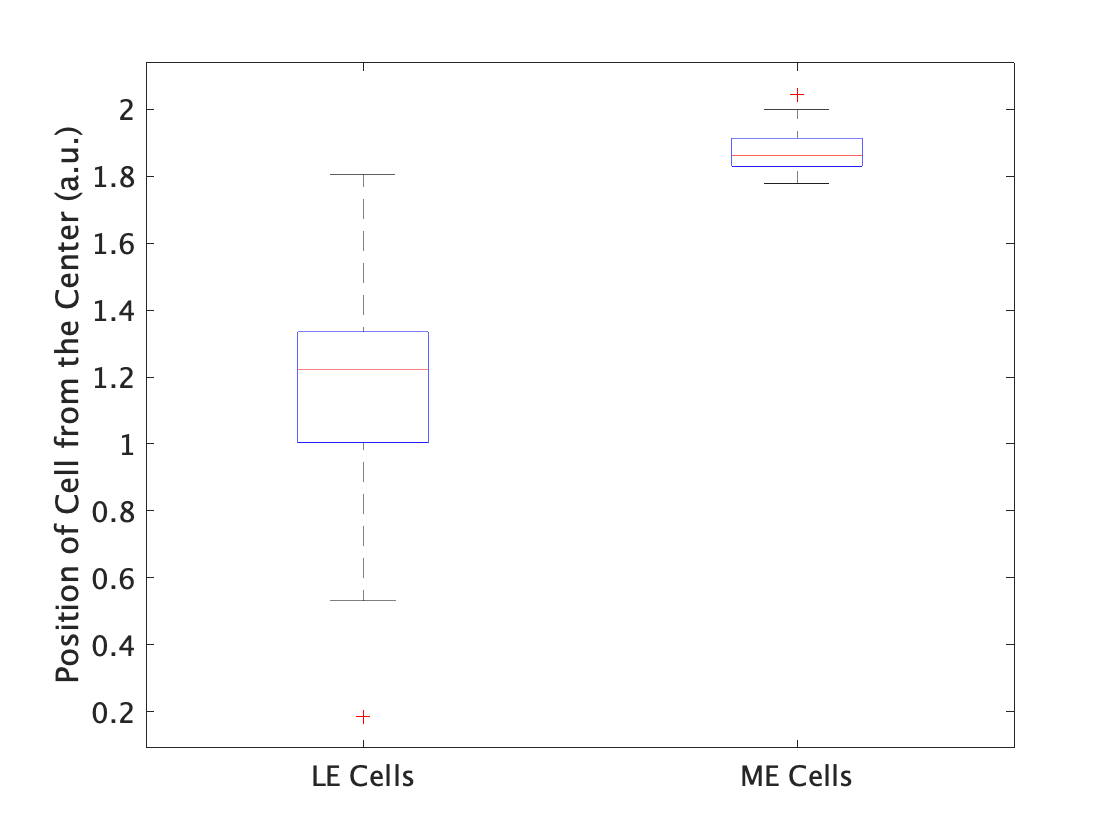

% Box plot final position of cells

figure 

LEB1KOluminal = LEB1KO_1_r(end,:);
LEB1KOmyo = LEB1KO_1_r2(end,:);
g = [LEB1KOluminal LEB1KOmyo];
C = [zeros(1,length(LEB1KOluminal)) ones(1,length(LEB1KOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_LEB1KO.tiff');

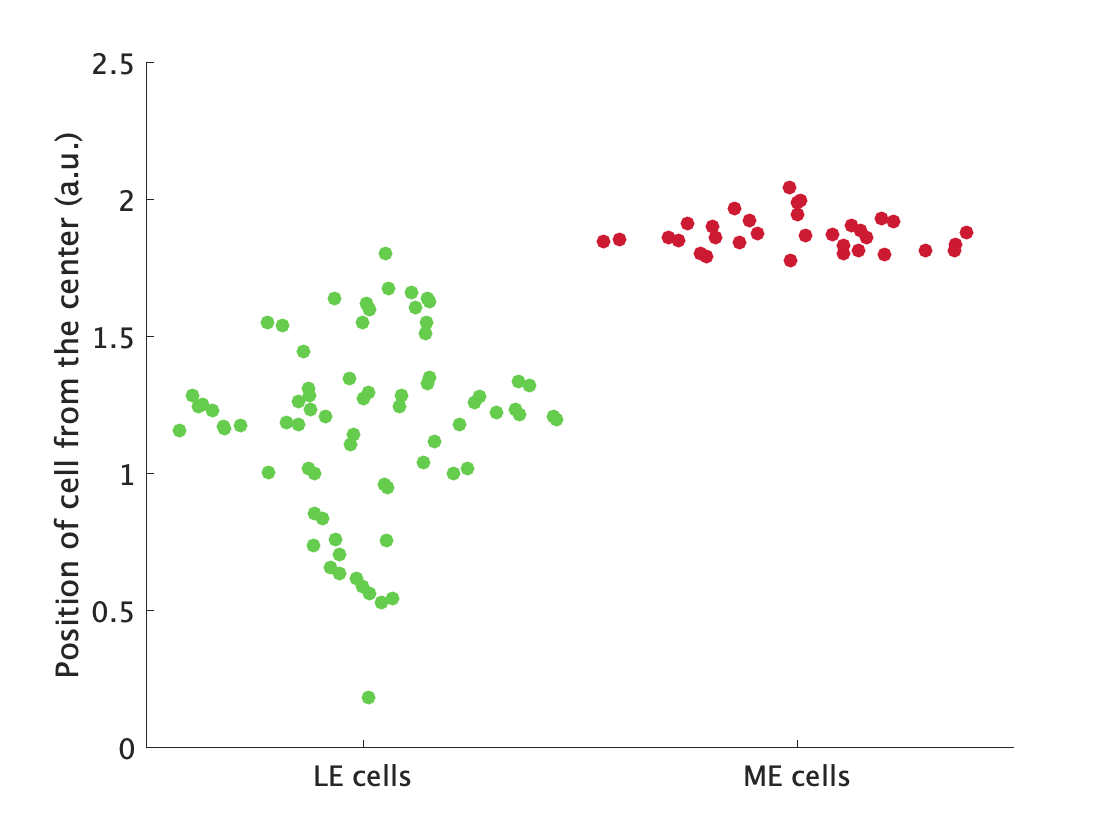

clf

LEB1KOluminal = LEB1KO_1_r(end,:);
LE1 = LEB1KOluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

LEB1KOmyo = LEB1KO_1_r2(end,:);
ME1 = LEB1KOmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_LEB1KO.tiff');

movefile('CellPosition_LEB1KO.tiff', folder);

## LE KO

### n=1

LEKO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEDOKO/n=1/results_from_time_0/location.dat";
[LEKO_1_LuminalLocation, LEKO_1_MyoepithelialLocation, LEKO_1_r, LEKO_1_r2] = CellPosition(LEKO_1);

### n=2

LEKO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEDOKO/n=2/results_from_time_0/location.dat";
[LEKO_2_LuminalLocation, LEKO_2_MyoepithelialLocation, LEKO_2_r, LEKO_2_r2] = CellPosition(LEKO_2);

### n=3

LEKO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEDOKO/n=3/results_from_time_0/location.dat";
[LEKO_3_LuminalLocation, LEKO_3_MyoepithelialLocation, LEKO_3_r, LEKO_3_r2] = CellPosition(LEKO_3);

### n=4

LEKO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEDOKO/n=4/results_from_time_0/location.dat";
[LEKO_4_LuminalLocation, LEKO_4_MyoepithelialLocation, LEKO_4_r, LEKO_4_r2] = CellPosition(LEKO_4);

### n=5

LEKO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/LEDOKO/n=5/results_from_time_0/location.dat";
[LEKO_5_LuminalLocation, LEKO_5_MyoepithelialLocation, LEKO_5_r, LEKO_5_r2] = CellPosition(LEKO_5);

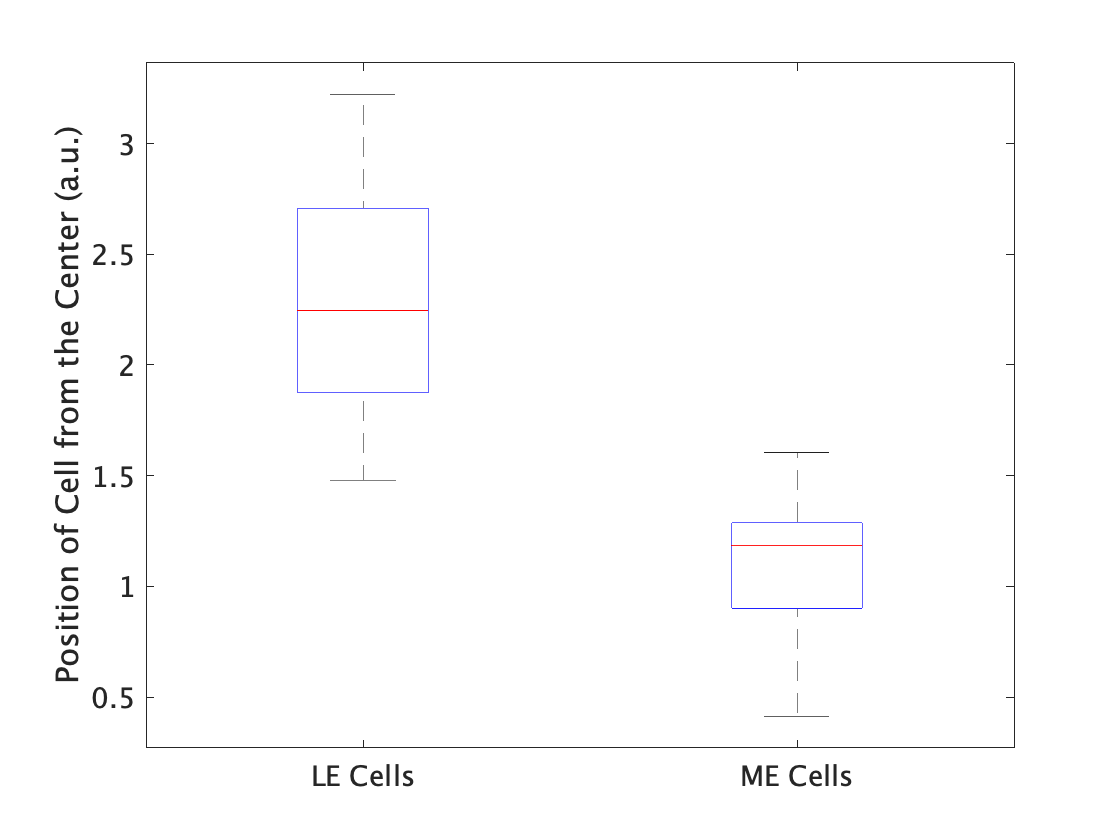

% Box plot final position of cells

figure 

LEKOluminal = LEKO_1_r(end,:);
LEKOmyo = LEKO_1_r2(end,:);
g = [LEKOluminal LEKOmyo];
C = [zeros(1,length(LEKOluminal)) ones(1,length(LEKOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_LEKO.tiff');

movefile('CellPosition_LEKO.tiff', folder);

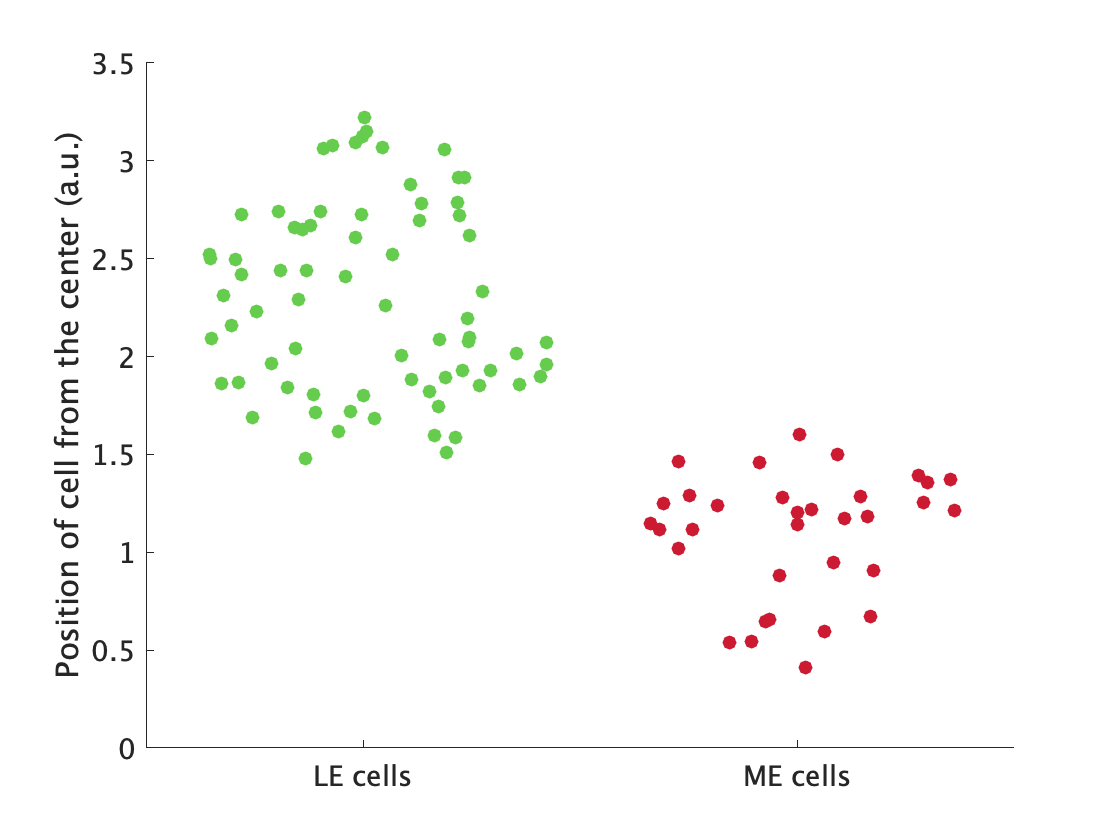

clf

LEKOluminal = LEKO_1_r(end,:);
LE1 = LEKOluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

LEKOmyo = LEKO_1_r2(end,:);
ME1 = LEKOmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_LEKO.tiff');

movefile('CellPosition_LEKO.tiff', folder);

## DO KO

### n=1

DOKO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=1/results_from_time_0/location.dat";
[DOKO_1_LuminalLocation, DOKO_1_MyoepithelialLocation, DOKO_1_r, DOKO_1_r2] = CellPosition(DOKO_1);

### n=2

DOKO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=2/results_from_time_0/location.dat";
[DOKO_2_LuminalLocation, DOKO_2_MyoepithelialLocation, DOKO_2_r, DOKO_2_r2] = CellPosition(DOKO_2);

### n=3

DOKO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=3/results_from_time_0/location.dat";
[DOKO_3_LuminalLocation, DOKO_3_MyoepithelialLocation, DOKO_3_r, DOKO_3_r2] = CellPosition(DOKO_3);

### n=4

DOKO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=4/results_from_time_0/location.dat";
[DOKO_4_LuminalLocation, DOKO_4_MyoepithelialLocation, DOKO_4_r, DOKO_4_r2] = CellPosition(DOKO_4);

### n=5

DOKO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/DOKO/n=5/results_from_time_0/location.dat";
[DOKO_5_LuminalLocation, DOKO_5_MyoepithelialLocation, DOKO_5_r, DOKO_5_r2] = CellPosition(DOKO_5);

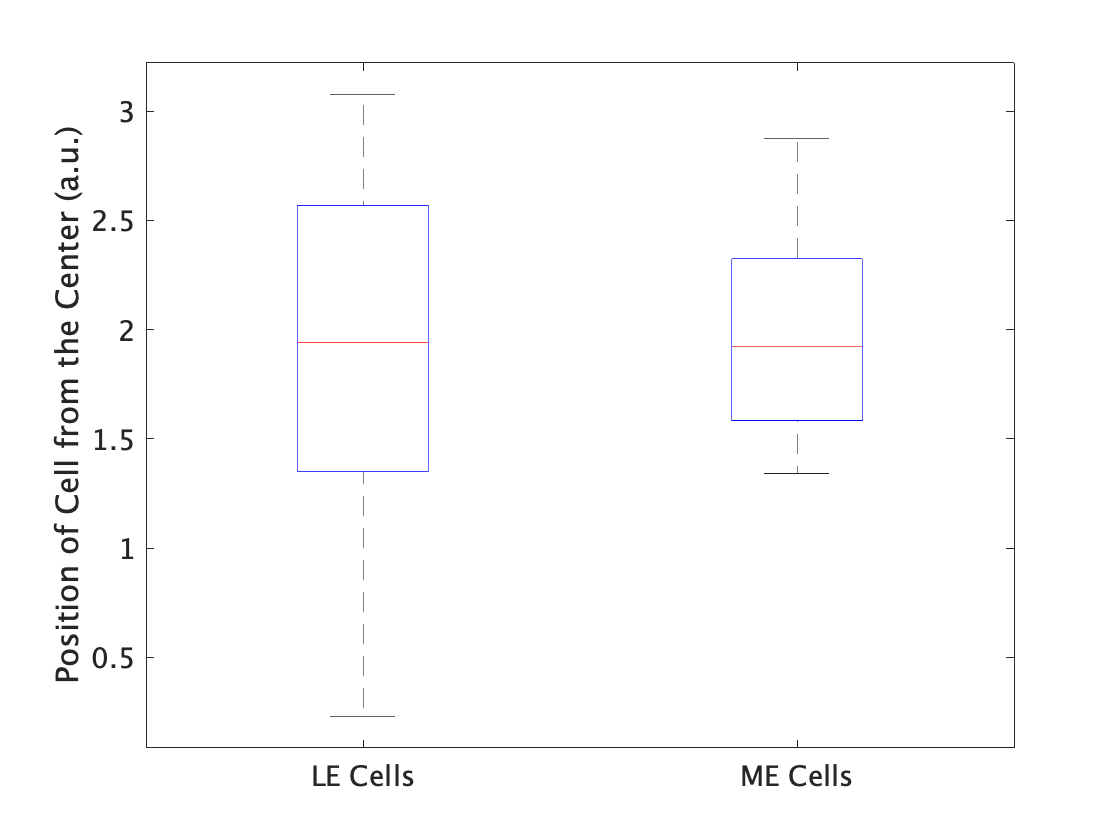

% Box plot final position of cells

figure 

DOKOluminal = DOKO_1_r(end,:);
DOKOmyo = DOKO_1_r2(end,:);
g = [DOKOluminal DOKOmyo];
C = [zeros(1,length(DOKOluminal)) ones(1,length(DOKOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_DOKO.tiff');

movefile('CellPosition_DOKO.tiff', folder);

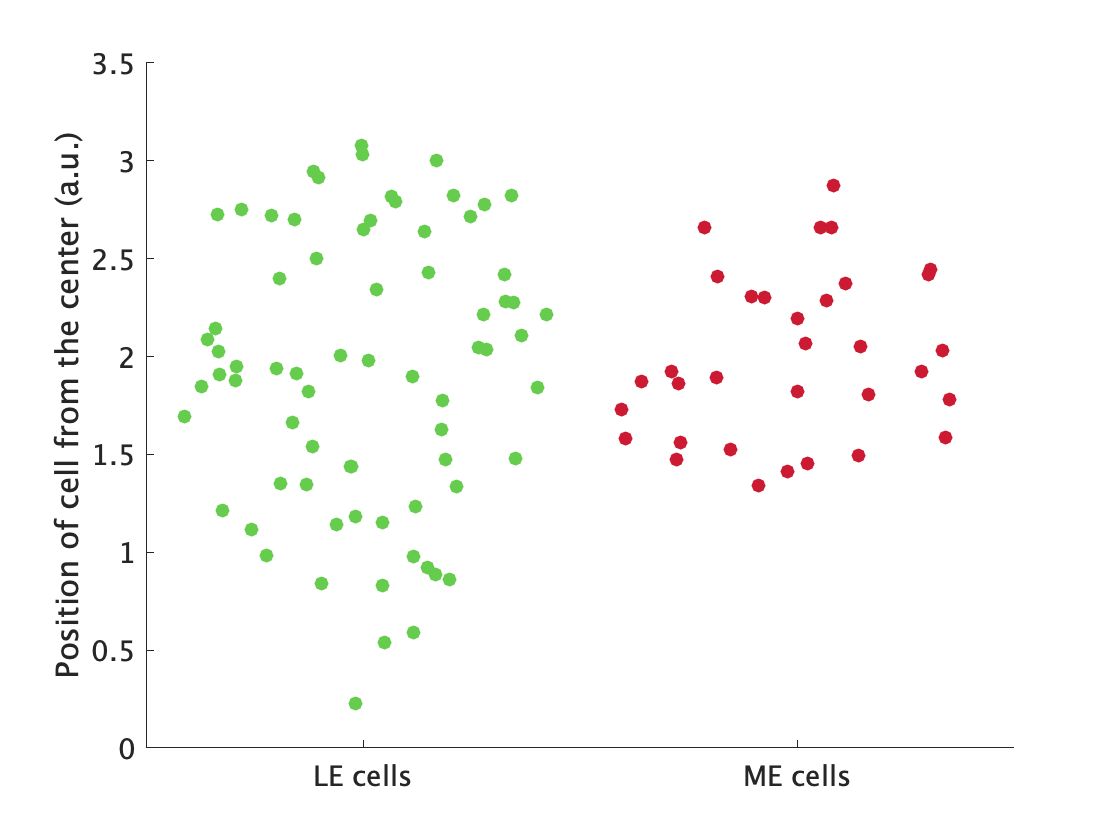

clf

DOKOluminal = DOKO_1_r(end,:);
LE1 = DOKOluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

DOKOmyo = DOKO_1_r2(end,:);
ME1 = DOKOmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_DOKO.tiff');

movefile('CellPosition_DOKO.tiff', folder);

% combine data from all experiments
DOKOLEposition = cat(1,DOKO_1_r(end,:),DOKO_2_r(end,:),DOKO_3_r(end,:),DOKO_4_r(end,:),DOKO_5_r(end,:));
DOKOMEposition = cat(1,DOKO_1_r2(end,:),DOKO_2_r2(end,:),DOKO_3_r2(end,:),DOKO_4_r2(end,:),DOKO_5_r2(end,:));

%Calculate Mean
DOKOLEaverage = mean(DOKOLEposition,2);
DOKOMEaverage = mean(DOKOMEposition,2);

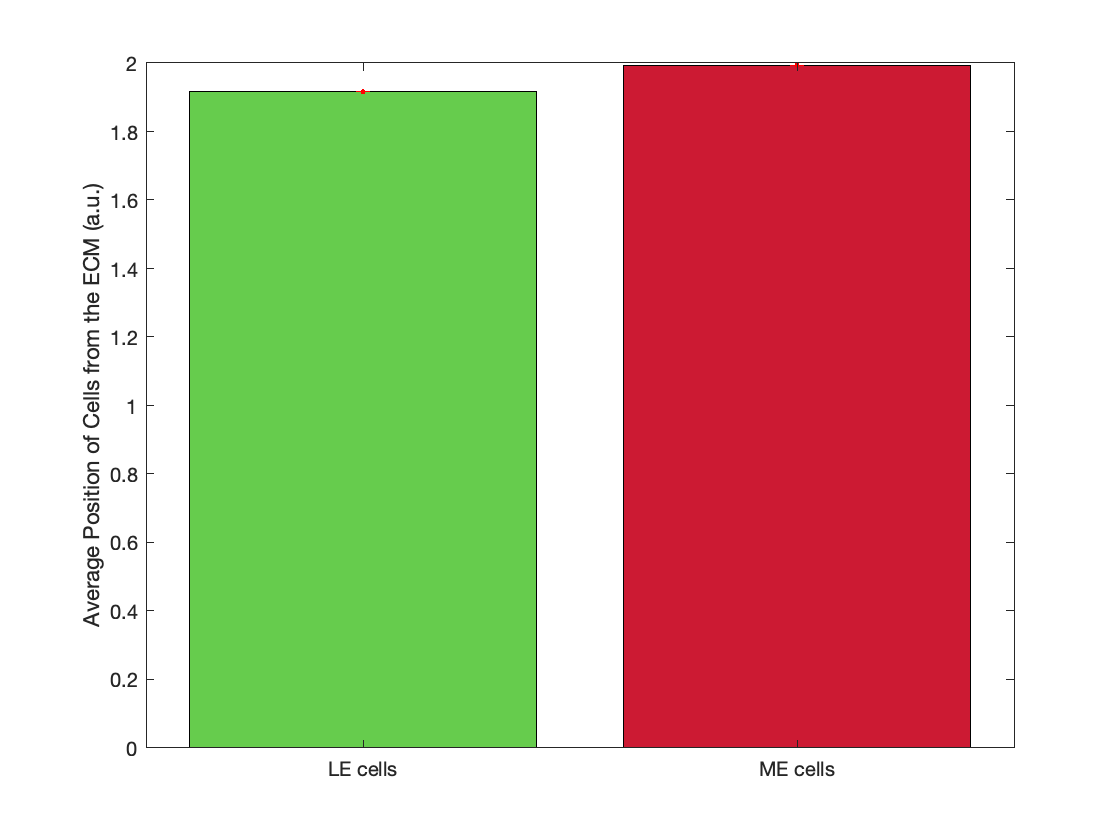

% plot average position of cells include data from all n=5 

%Calculate Mean and Standard Deviation
DOKOmeanLE = mean(DOKOLEaverage);
DOKOmeanME = mean(DOKOMEaverage);

y = cat(2,DOKOmeanLE, DOKOmeanME);

DOKOstdLE = std(DOKOLEaverage);
DOKOstdME = std(DOKOMEaverage);

error = cat(2,DOKOstdLE, DOKOstdME);

x=categorical({'LE cells', 'ME cells'});

b = bar(x,y);

%Make SD error bars 
hold on
errorbar(x,y, error, '.r')
hold off

ylabel('Average Position of Cells from the ECM (a.u.)') 
ax.XTickLabels = {'LE Cells', 'ME Cells'};

b.FaceColor = 'flat';
b.CData(1,:) = [.4 .8 .3];
b.CData(2,:) = [.8 .1 .2];

hold off

folder = '~/Desktop/';
exportgraphics(gca, 'AverageCellPosition_DOKO.pdf');

movefile('AverageCellPosition_DOKO.pdf', folder);

## Wild Type LoF MEDOKO

### n=1

MEDOKO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/MEDOKO/n=1/results_from_time_0/location.dat";
[MEDOKO_1_LuminalLocation, MEDOKO_1_MyoepithelialLocation, MEDOKO_1_r, MEDOKO_1_r2] = CellPosition(MEDOKO_1);

### n=2

MEDOKO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/MEDOKO/n=2/results_from_time_0/location.dat";
[MEDOKO_2_LuminalLocation, MEDOKO_2_MyoepithelialLocation, MEDOKO_2_r, MEDOKO_2_r2] = CellPosition(MEDOKO_2);

### n=3

MEDOKO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/MEDOKO/n=3/results_from_time_0/location.dat";
[MEDOKO_3_LuminalLocation, MEDOKO_3_MyoepithelialLocation, MEDOKO_3_r, MEDOKO_3_r2] = CellPosition(MEDOKO_3);

### n=4

MEDOKO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/MEDOKO/n=4/results_from_time_0/location.dat";
[MEDOKO_4_LuminalLocation, MEDOKO_4_MyoepithelialLocation, MEDOKO_4_r, MEDOKO_4_r2] = CellPosition(MEDOKO_4);

### n=5

MEDOKO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/MEDOKO/n=5/results_from_time_0/location.dat";
[MEDOKO_5_LuminalLocation, MEDOKO_5_MyoepithelialLocation, MEDOKO_5_r, MEDOKO_5_r2] = CellPosition(MEDOKO_5);

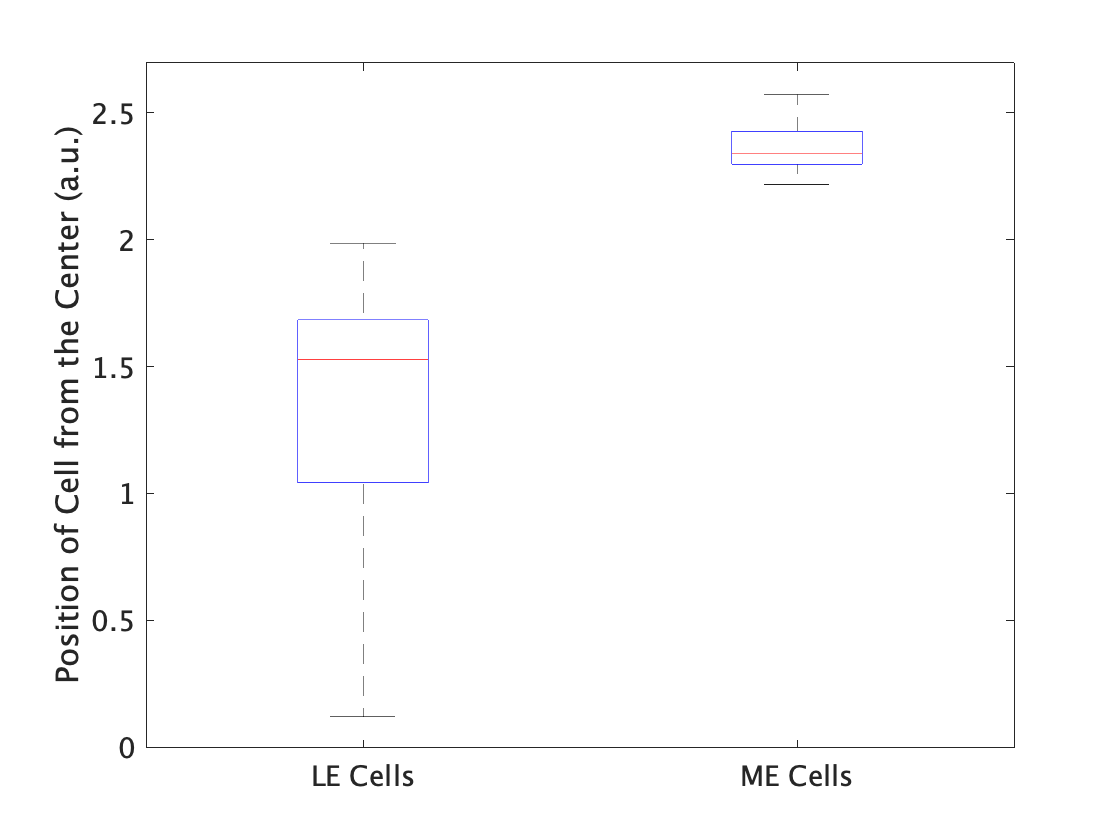

% Box plot final position of cells

figure 

MEDOKOluminal = MEDOKO_1_r(end,:);
MEDOKOmyo = MEDOKO_1_r2(end,:);
g = [MEDOKOluminal MEDOKOmyo];
C = [zeros(1,length(MEDOKOluminal)) ones(1,length(MEDOKOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_MEDOKO.tiff');

movefile('CellPosition_MEDOKO.tiff', folder);

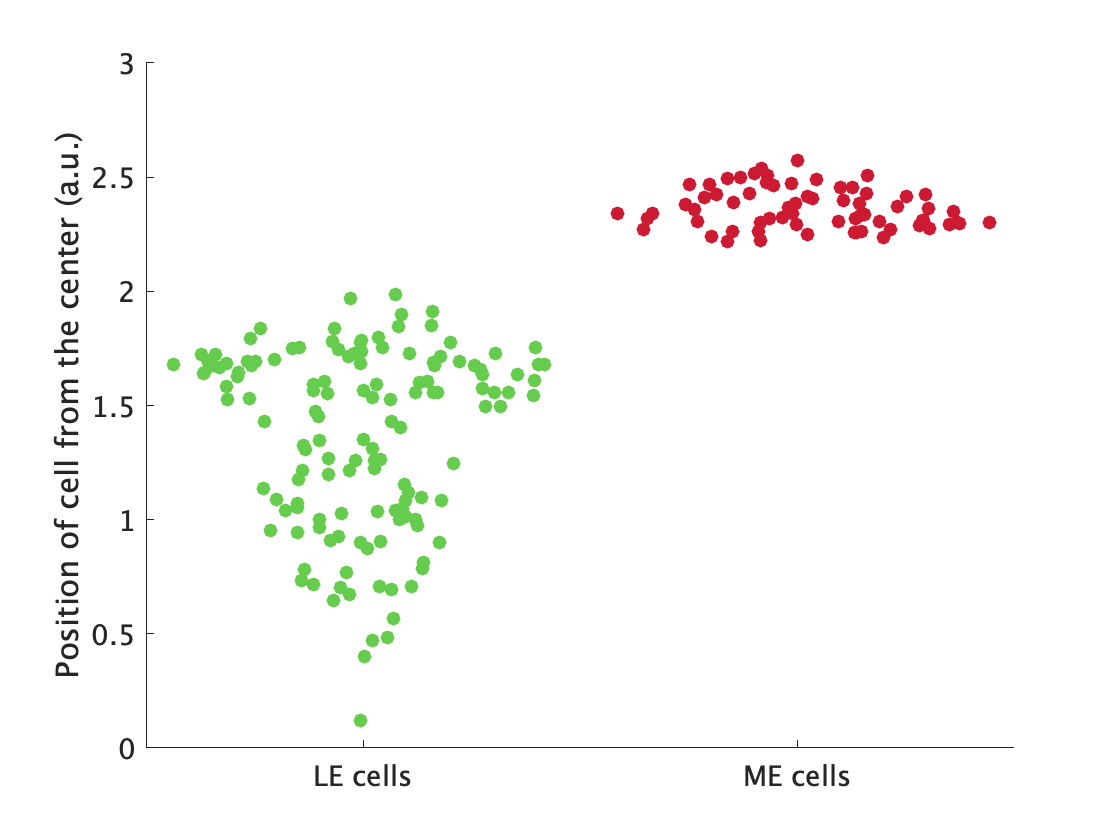

clf

MEDOKOluminal = MEDOKO_1_r(end,:);
LE1 = MEDOKOluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

MEDOKOmyo = MEDOKO_1_r2(end,:);
ME1 = MEDOKOmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_MEDOKO.tiff');

movefile('CellPosition_MEDOKO.tiff', folder);

## WT LoF DO KO

### n=1

DOKO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/DOKO/n=1/results_from_time_0/location.dat";
[DOKO_1_LuminalLocation, DOKO_1_MyoepithelialLocation, DOKO_1_r, DOKO_1_r2] = CellPosition(DOKO_1);

### n=2

DOKO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/DOKO/n=2/results_from_time_0/location.dat";
[DOKO_2_LuminalLocation, DOKO_2_MyoepithelialLocation, DOKO_2_r, DOKO_2_r2] = CellPosition(DOKO_2);

### n=3

DOKO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/DOKO/n=3/results_from_time_0/location.dat";
[DOKO_3_LuminalLocation, DOKO_3_MyoepithelialLocation, DOKO_3_r, DOKO_3_r2] = CellPosition(DOKO_3);

### n=4

DOKO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/DOKO/n=4/results_from_time_0/location.dat";
[DOKO_4_LuminalLocation, DOKO_4_MyoepithelialLocation, DOKO_4_r, DOKO_4_r2] = CellPosition(DOKO_4);

### n=5

DOKO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/DOKO/n=5/results_from_time_0/location.dat";
[DOKO_5_LuminalLocation, DOKO_5_MyoepithelialLocation, DOKO_5_r, DOKO_5_r2] = CellPosition(DOKO_5);

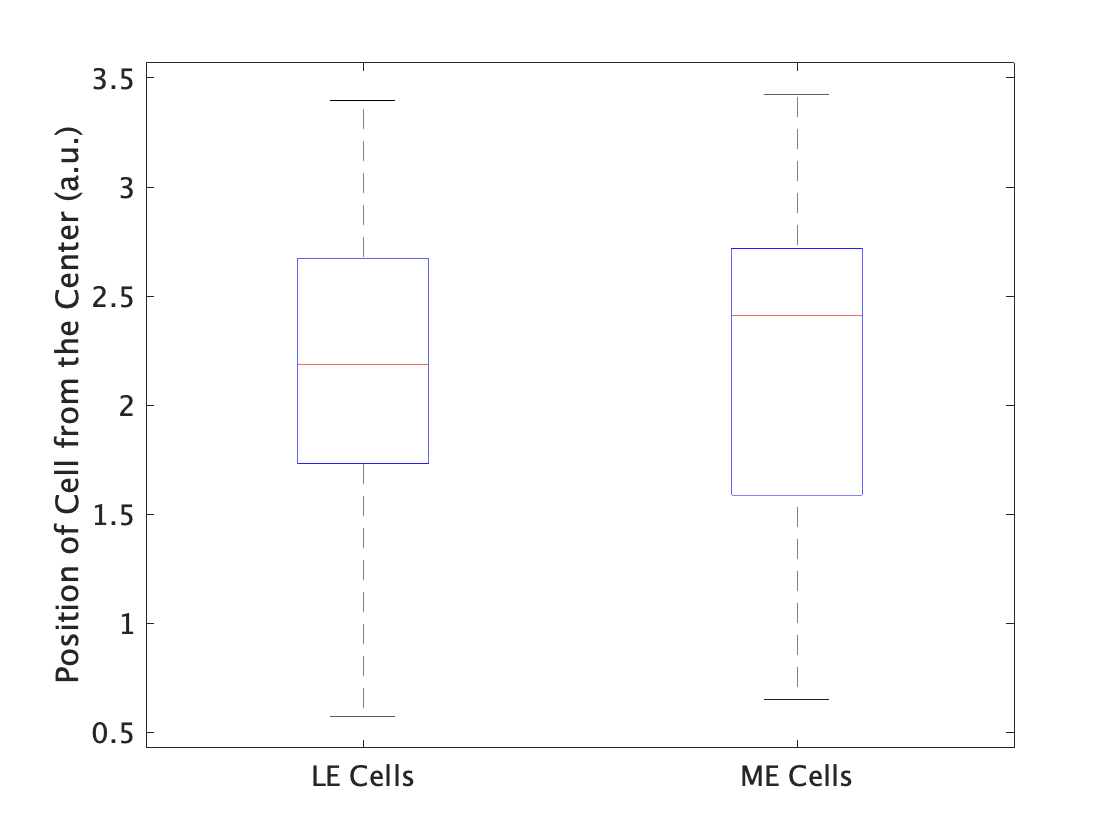

% Box plot final position of cells

figure 

DOKOluminal = DOKO_1_r(end,:);
DOKOmyo = DOKO_1_r2(end,:);
g = [DOKOluminal DOKOmyo];
C = [zeros(1,length(DOKOluminal)) ones(1,length(DOKOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_DOKO.tiff');

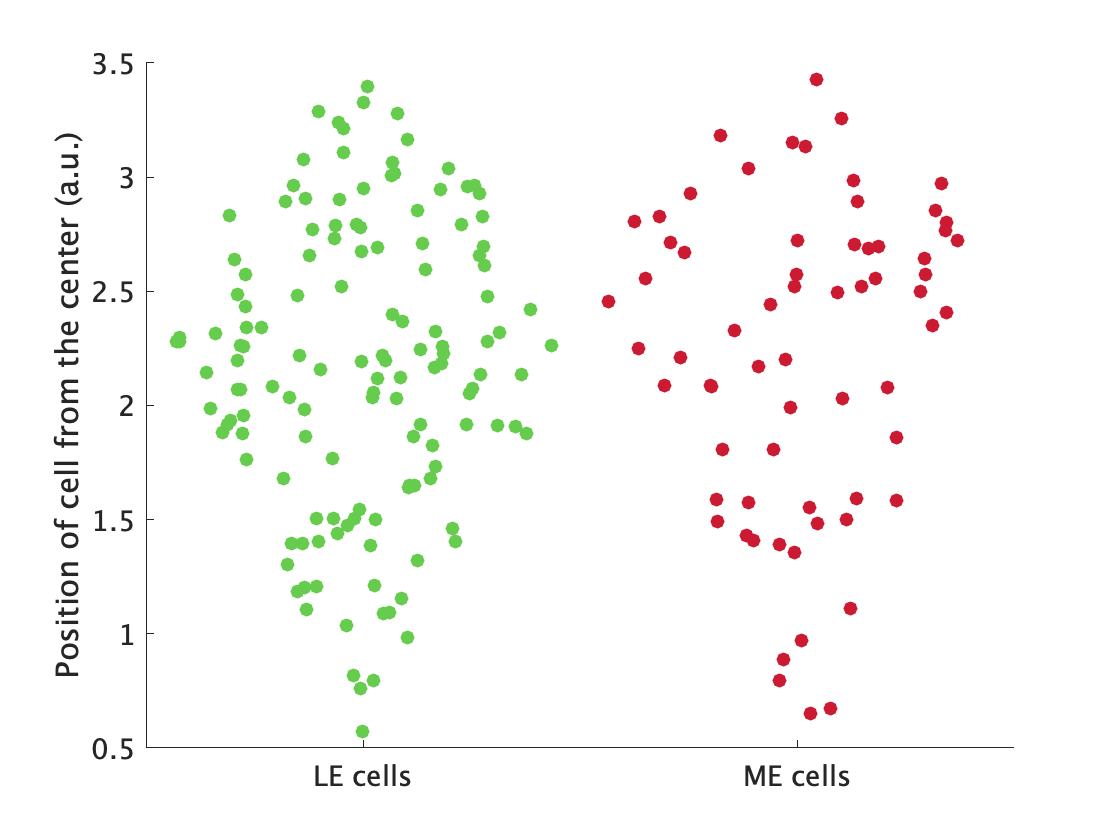

clf

DOKOluminal = DOKO_1_r(end,:);
LE1 = DOKOluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

DOKOmyo = DOKO_1_r2(end,:);
ME1 = DOKOmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_DOKO.tiff');

movefile('CellPosition_DOKO.tiff', folder);

## WT LoF LE DO KO

### n=1

DOKO_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/LEDOKO/n=1/results_from_time_0/location.dat";
[DOKO_1_LuminalLocation, DOKO_1_MyoepithelialLocation, DOKO_1_r, DOKO_1_r2] = CellPosition(DOKO_1);

### n=2

DOKO_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/LEDOKO/n=2/results_from_time_0/location.dat";
[DOKO_2_LuminalLocation, DOKO_2_MyoepithelialLocation, DOKO_2_r, DOKO_2_r2] = CellPosition(DOKO_2);

### n=3

DOKO_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/LEDOKO/n=3/results_from_time_0/location.dat";
[DOKO_3_LuminalLocation, DOKO_3_MyoepithelialLocation, DOKO_3_r, DOKO_3_r2] = CellPosition(DOKO_3);

### n=4

DOKO_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/LEDOKO/n=4/results_from_time_0/location.dat";
[DOKO_4_LuminalLocation, DOKO_4_MyoepithelialLocation, DOKO_4_r, DOKO_4_r2] = CellPosition(DOKO_4);

### n=5

DOKO_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/LoF/LEDOKO/n=5/results_from_time_0/location.dat";
[DOKO_5_LuminalLocation, DOKO_5_MyoepithelialLocation, DOKO_5_r, DOKO_5_r2] = CellPosition(DOKO_5);

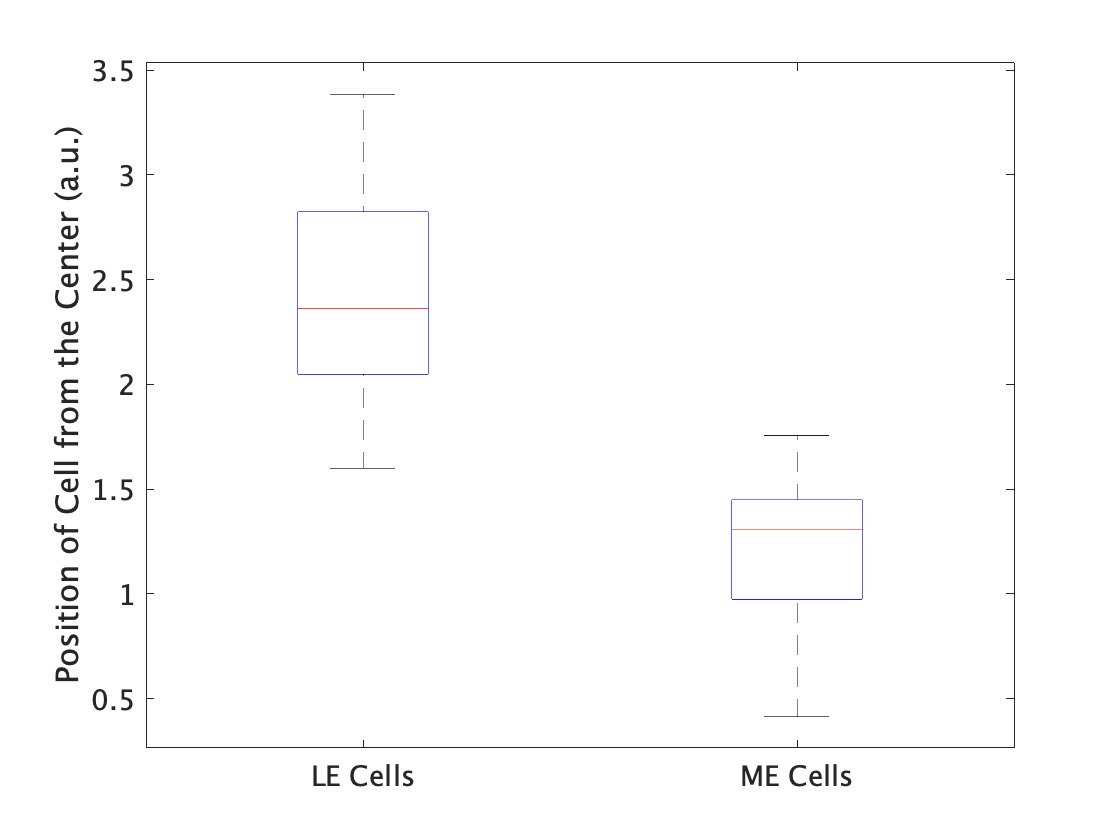

% Box plot final position of cells

figure 

DOKOluminal = DOKO_1_r(end,:);
DOKOmyo = DOKO_1_r2(end,:);
g = [DOKOluminal DOKOmyo];
C = [zeros(1,length(DOKOluminal)) ones(1,length(DOKOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_LEDOKO.tiff');

clf

LEKOluminal = LEKO_1_r(end,:);
LE1 = LEKOluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

LEKOmyo = LEKO_1_r2(end,:);
ME1 = LEKOmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_LEKO.tiff');

movefile('CellPosition_LEKO.tiff', folder);

## GoF ME DO KI

### n=1

MEGOF_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/MEDOKI/n=1/results_from_time_0/location.dat";
[MEGOF_1_LuminalLocation, MEGOF_1_MyoepithelialLocation, MEGOF_1_r, MEGOF_1_r2] = CellPosition(MEGOF_1);

### n=2

MEGOF_2 = "Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/MEDOKI/n=2/results_from_time_0/location.dat";
[MEGOF_2_LuminalLocation, MEGOF_2_MyoepithelialLocation, MEGOF_2_r, MEGOF_2_r2] = CellPosition(MEGOF_2);

Error using matlab.io.ImportOptions/readmatrix (line 679)
Unable to find or open 'Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/MEDOKI/n=1/results_from_time_0/location.dat'. Check the path and filename or file permissions.

Error in importfile_displacement (<a href="matlab: opentoline('/Users/Priya/Documents/GitHub/PriyaN/MATLAB/importfile_displacement.m',46,0)">line 46</

### n=3

MEGOF_3 = "Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/MEDOKI/n=3/results_from_time_0/location.dat";
[MEGOF_3_LuminalLocation, MEGOF_3_MyoepithelialLocation, MEGOF_3_r, MEGOF_3_r2] = CellPosition(MEGOF_3);

### n=4

MEGOF_4 = "Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/MEDOKI/n=4/results_from_time_0/location.dat";
[MEGOF_4_LuminalLocation, MEGOF_4_MyoepithelialLocation, MEGOF_4_r, MEGOF_4_r2] = CellPosition(MEGOF_4);

### n=5

MEGOF_5 = "Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/MEDOKI/n=5/results_from_time_0/location.dat";
[MEGOF_5_LuminalLocation, MEGOF_5_MyoepithelialLocation, MEGOF_5_r, MEGOF_5_r2] = CellPosition(MEGOF_5);

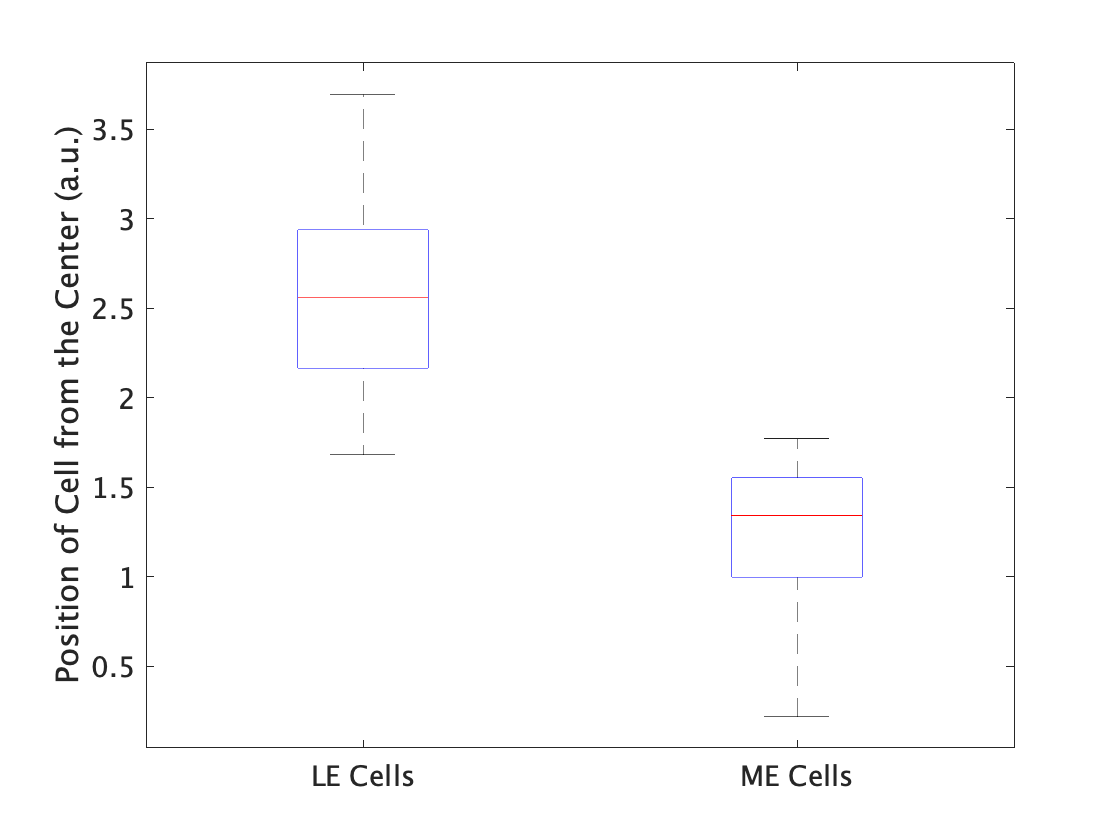

% Box plot final position of cells

figure 

WTluminal = WT_1_r(end,:);
WTmyo = WT_1_r2(end,:);
g = [WTluminal WTmyo];
C = [zeros(1,length(WTluminal)) ones(1,length(WTmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_GoF_MEDOKI.tiff');

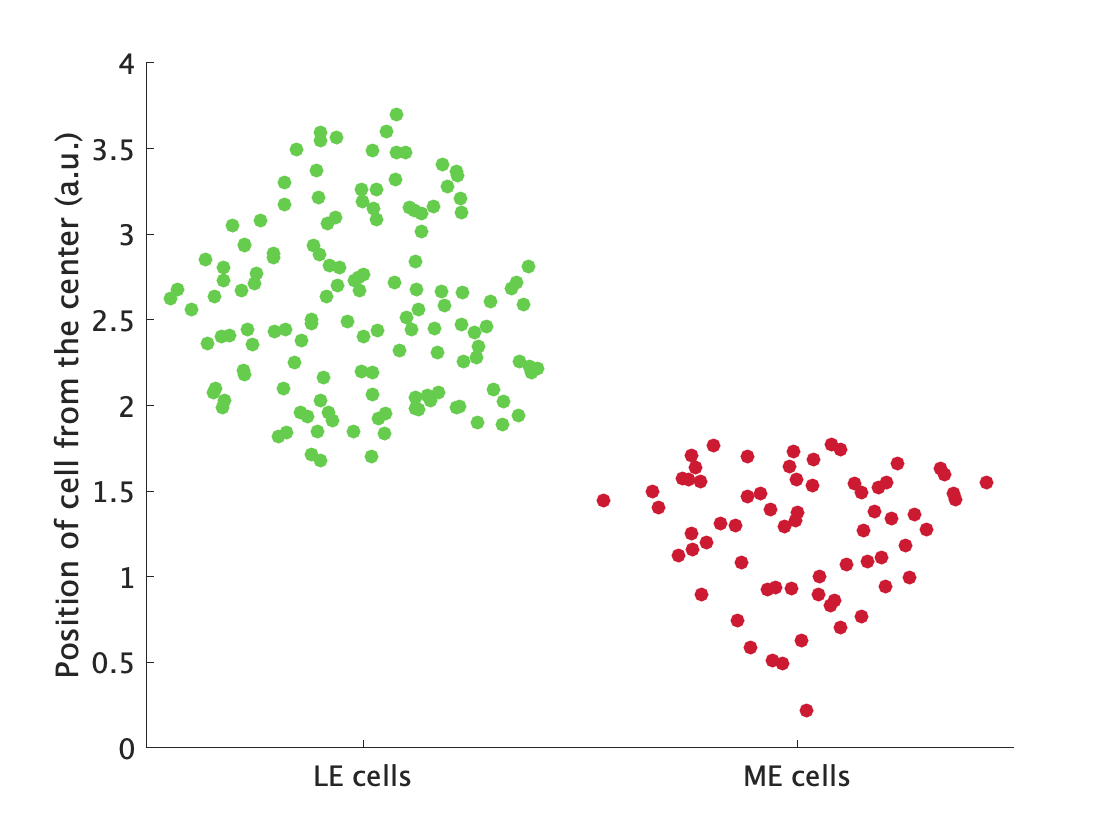

clf

MEGOFluminal = MEGOF_1_r(end,:);
LE1 = MEGOFluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

MEGOFmyo = MEGOF_1_r2(end,:);
ME1 = MEGOFmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_MEGOF.tiff');

movefile('CellPosition_MEGOF.tiff', folder);

## GoF LE DO KI

### n=1

LEGOF_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/LEDOKI/n=1/results_from_time_0/location.dat";
[LEGOF_1_LuminalLocation, LEGOF_1_MyoepithelialLocation, LEGOF_1_r, LEGOF_1_r2] = CellPosition(LEGOF_1);

### n=2

LEGOF_2 = "Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/LEDOKI/n=2/results_from_time_0/location.dat";
[LEGOF_2_LuminalLocation, LEGOF_2_MyoepithelialLocation, LEGOF_2_r, LEGOF_2_r2] = CellPosition(LEGOF_2);

Error using matlab.io.ImportOptions/readmatrix (line 679)
Unable to find or open 'Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/LEDOKI/n=2/results_from_time_0/location.dat'. Check the path and filename or file permissions.

Error in importfile_displacement (<a href="matlab: opentoline('/Users/Priya/Documents/GitHub/PriyaN/MATLAB/importfile_displacement.m',46,0)">line 46</

### n=3

LEGOF_3 = "Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/LEDOKI/n=3/results_from_time_0/location.dat";
[LEGOF_3_LuminalLocation, LEGOF_3_MyoepithelialLocation, LEGOF_3_r, LEGOF_3_r2] = CellPosition(LEGOF_3);

### n=4

LEGOF_4 = "Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/LEDOKI/n=4/results_from_time_0/location.dat";
[LEGOF_4_LuminalLocation, LEGOF_4_MyoepithelialLocation, LEGOF_4_r, LEGOF_4_r2] = CellPosition(LEGOF_4);

### n=5

LEGOF_5 = "Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/LEDOKI/n=5/results_from_time_0/location.dat";
[LEGOF_5_LuminalLocation, LEGOF_5_MyoepithelialLocation, LEGOF_5_r, LEGOF_5_r2] = CellPosition(LEGOF_5);

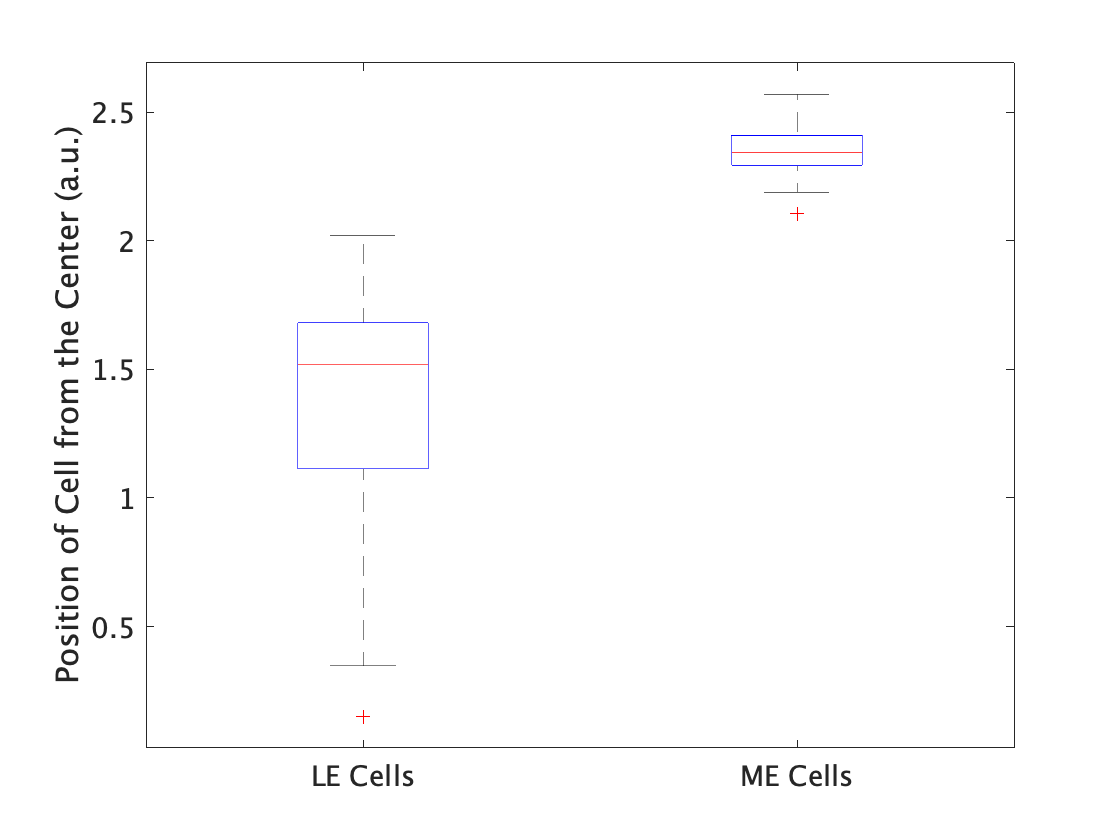

% Box plot final position of cells

figure 

WTluminal = WT_1_r(end,:);
WTmyo = WT_1_r2(end,:);
g = [WTluminal WTmyo];
C = [zeros(1,length(WTluminal)) ones(1,length(WTmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_GoF_LEDOKI.tiff');

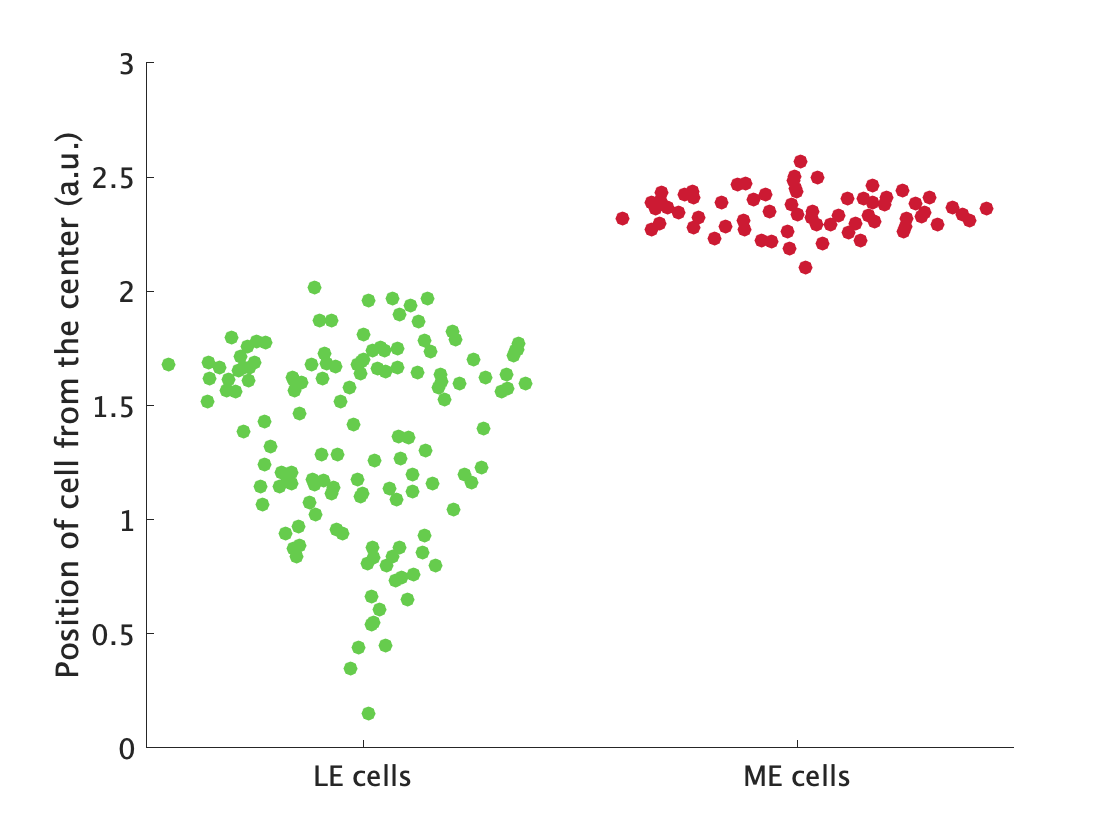

clf

LEGOFluminal = LEGOF_1_r(end,:);
LE1 = LEGOFluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

LEGOFmyo = LEGOF_1_r2(end,:);
ME1 = LEGOFmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_LEGOF.tiff');

movefile('CellPosition_LEGOF.tiff', folder);

## GoF DO KI

### n=1

DOGOF_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/DOKI/n=1/results_from_time_0/location.dat";
[DOGOF_1_LuminalLocation, DOGOF_1_MyoepithelialLocation, DOGOF_1_r, DOGOF_1_r2] = CellPosition(DOGOF_1);

### n=2

DOGOF_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/DOKI/n=2/results_from_time_0/location.dat";
[DOGOF_2_LuminalLocation, DOGOF_2_MyoepithelialLocation, DOGOF_2_r, DOGOF_2_r2] = CellPosition(DOGOF_2);

### n=3

DOGOF_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/DOKI/n=3/results_from_time_0/location.dat";
[DOGOF_3_LuminalLocation, DOGOF_3_MyoepithelialLocation, DOGOF_3_r, DOGOF_3_r2] = CellPosition(DOGOF_3);

### n=4

DOGOF_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/DOKI/n=4/results_from_time_0/location.dat";
[DOGOF_4_LuminalLocation, DOGOF_4_MyoepithelialLocation, DOGOF_4_r, DOGOF_4_r2] = CellPosition(DOGOF_4);

### n=5

DOGOF_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/IntegrinExpressionModifier/GoF/DOKI/n=5/results_from_time_0/location.dat";
[DOGOF_5_LuminalLocation, DOGOF_5_MyoepithelialLocation, DOGOF_5_r, DOGOF_5_r2] = CellPosition(DOGOF_5);

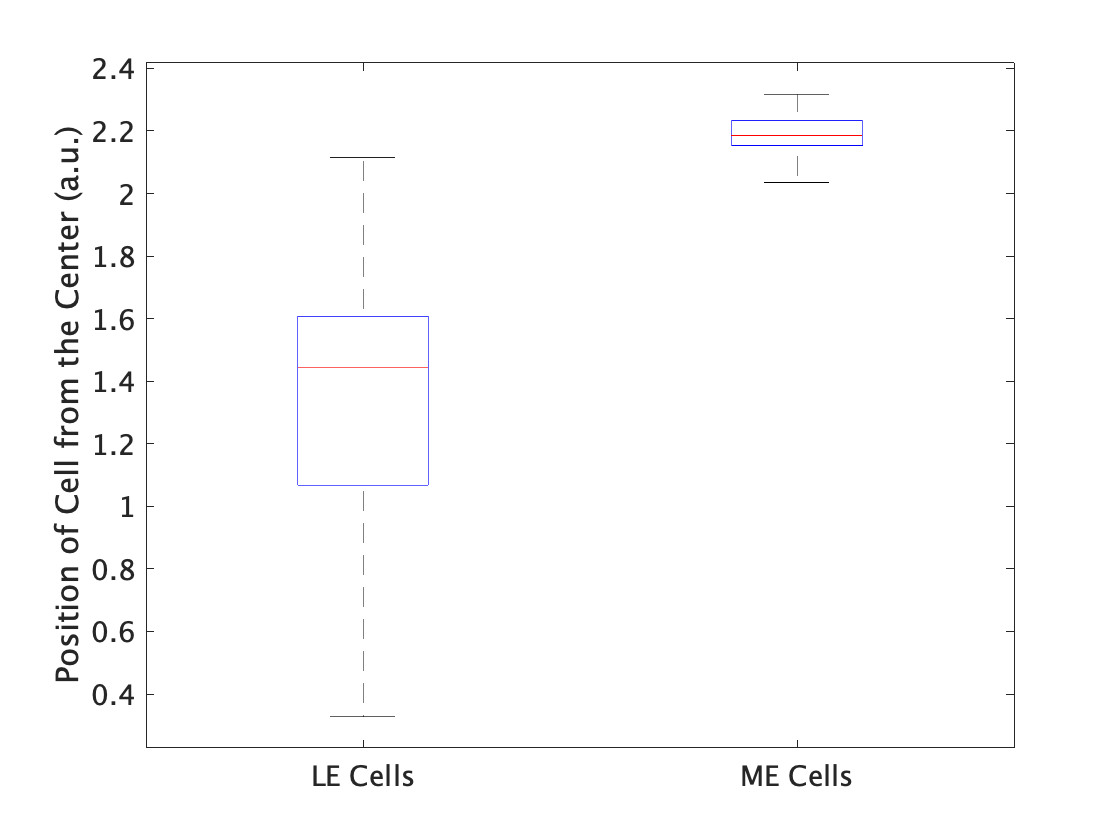

% Box plot final position of cells

figure 

DOKOluminal = DOKO_1_r(end,:);
DOKOmyo = DOKO_1_r2(end,:);
g = [DOKOluminal DOKOmyo];
C = [zeros(1,length(DOKOluminal)) ones(1,length(DOKOmyo))];

boxplot(g,C, 'Labels', {'LE Cells', 'ME Cells'})

ylabel ('Position of Cell from the Center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_GoF_DOKI.tiff');

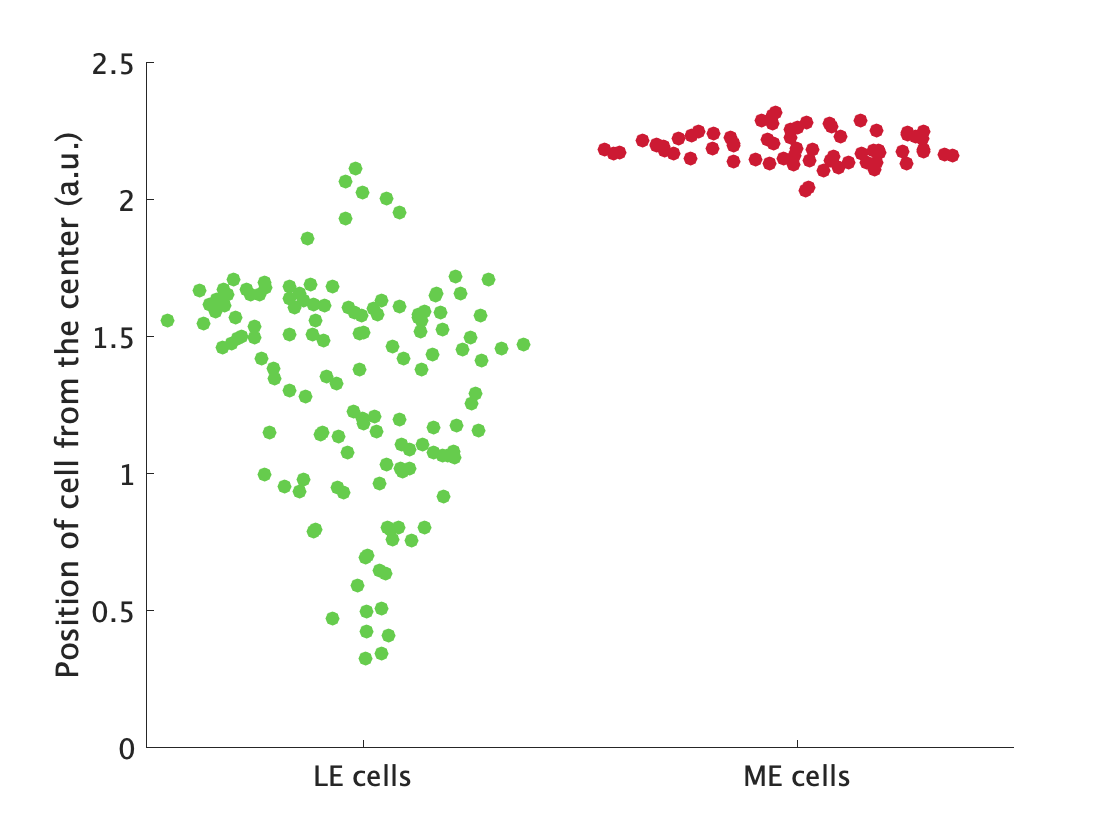

clf

DOGOFluminal = DOGOF_1_r(end,:);
LE1 = DOGOFluminal.';
LE2 = repmat({'LE cells'},size(LE1,1),1);

DOGOFmyo = DOGOF_1_r2(end,:);
ME1 = DOGOFmyo.';
ME2 = repmat({'ME cells'},size(ME1,1),1);

x = categorical(LE2);
c = [0.4 0.8 0.3];
x1 = categorical(ME2);
c1 = [0.8 0.1 0.2];

swarmchart(x,LE1,50,c,'filled')
hold on 
swarmchart(x1,ME1, 50,c1,'filled' )
hold off
ylabel ('Position of cell from the center (a.u.)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";
folder = '~/Desktop/';
exportgraphics(gca, 'CellPosition_DOGOF.tiff');

movefile('CellPosition_DOGOF.tiff', folder);